# Illustration des la double gaussienne et de la RQ

clear; clc;
tic

## Definition des variables contextuelles

pc = 'C:/Users/lehuen201/Melting_Potes_Amlh_Phd/';
% pc = 'K:/BOREA/Melting Potes/Melting_Potes_Amlh_Phd/'; % 
tsk = 'A_SDM/';
site = 'ES'; % ES for Seine estuary

wdpath = [pc 'Melting Pot/',tsk]; 
wdgraph = [wdpath,'Plots/HMS_Matlab/'];

plot_reso='-r600';

Surface gaussienne théorique

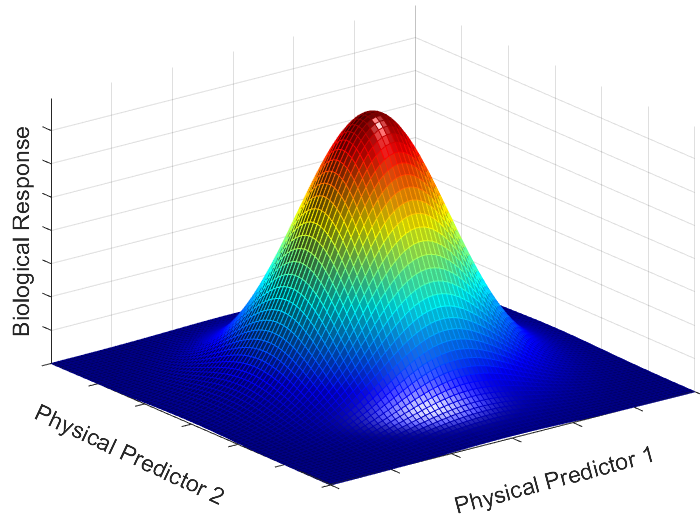

palette = 'jet';
N = 3.0;
x=linspace(-N, N,80); y=x;

[X,Y]=meshgrid(x,y);
Z=exp(-(X.^2/2)-(Y.^2/2))/sqrt(2*pi);
surf(X,Y,Z,'EdgeColor','flat'); %,'LineStyle','none'
% contourf(X,Y,Z,50, 'LineColor','flat'); colorbar;
xlabel('Physical Predictor 1','Rotation',15,'FontSize',14); 
ylabel('Physical Predictor 2','Rotation',-25,'FontSize',14); 
zlabel('Biological Response','FontSize',14);
colormap(palette); camlight; 
axis tight
set(gca,'XTickLabel',[], 'YTickLabel', [], 'ZTickLabel', [])
setTightMargins(.1)

print(gcf,sprintf('%sBifact_gauss3D.png',wdgraph),'-dpng',plot_reso);

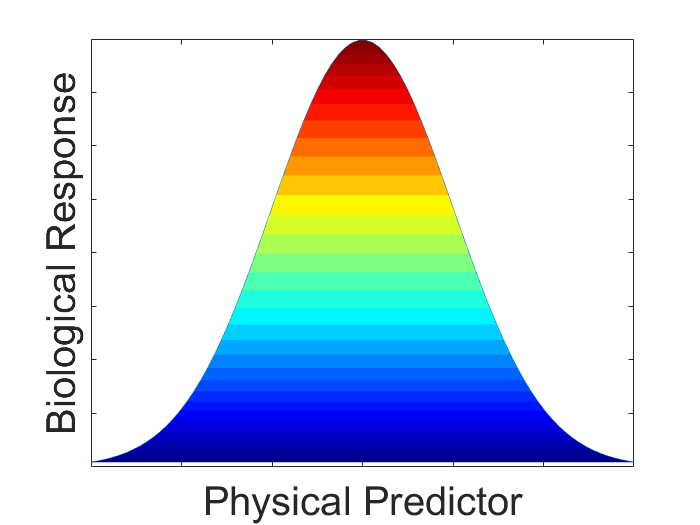


z=exp(-(x.^2/2))/sqrt(2*pi);
plot(x,z); hold on
N = numel(x);
for ii = ceil(N/2):N-1
       ix = [ii ii+1 N-ii N-ii+1];
%        disp(ix);
       patch(x(ix), z(ix), z(ii)*256/max(z(:)),'edgecolor', 'none');
end
xlabel('Physical Predictor','FontSize',24); ylabel('Biological Response','FontSize',24);
set(gca,'XTickLabel',[], 'YTickLabel', [], 'ZTickLabel', [])
hold off

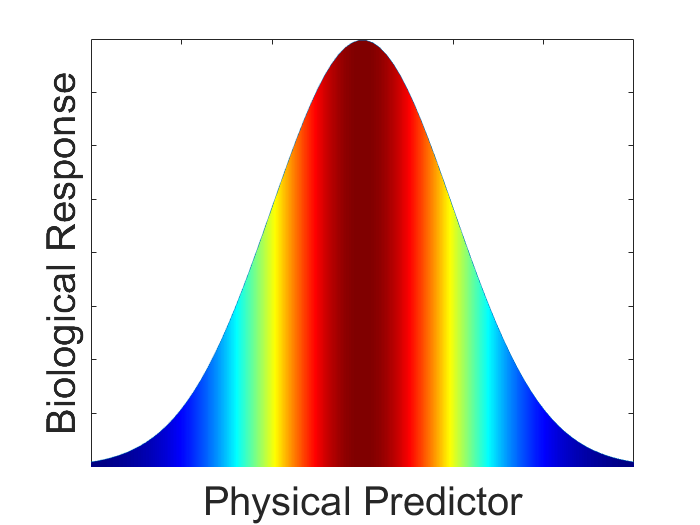


plot(x,z); hold on
verts = [x(:), z(:); x(:) zeros(N,1)];
q = (1:N-1)';
faces = [q, q+1, q+N+1, q+N];
p = patch('Faces', faces, 'Vertices', verts, 'FaceVertexCData', [z(:); z(:)], 'FaceColor', 'interp', 'EdgeColor', 'none');
xlabel('Physical Predictor','FontSize',24); ylabel('Biological Response','FontSize',24);
set(gca,'XTickLabel',[], 'YTickLabel', [], 'ZTickLabel', [])
hold off

Illustration de la régression quantile

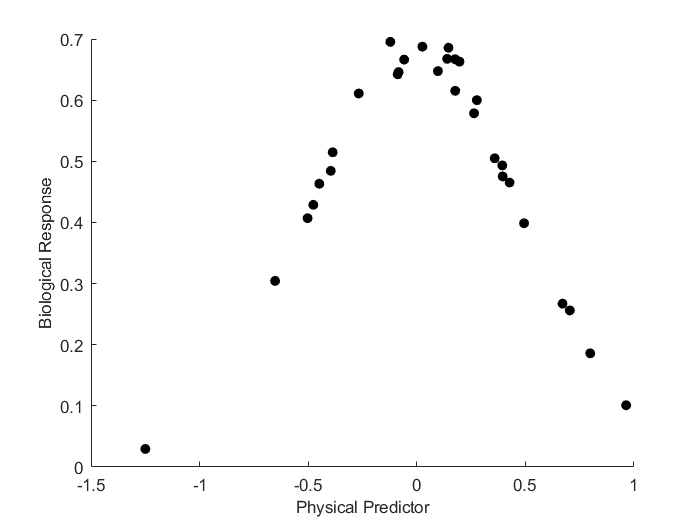

listcol=[0, 0.4470, 0.7410; %hsv(5);%
         0.8500, 0.3250, 0.0980;
         0.9290, 0.6940, 0.1250;
         0.4940, 0.1840, 0.5560;
         0.4660, 0.6740, 0.1880];%;
%          0.3010, 0.7450, 0.9330;
%          0.6350, 0.0780, 0.1840];
palette = 'jet';
N=30; mu=0; sigma=0.5;
limfact=[.25 .5 .75 .9];
xr=normrnd(mu,sigma,N,1); yr=linspace(.1,.9,N/5)';

z1=limfact(1).*normpdf(xr,mu,sigma).*(8.*rand(N,1))/10;
    zt1 = limfact(1).*normpdf(linspace(min(xr),max(xr),N),mu,sigma);
z2=limfact(2).*normpdf(xr,mu,sigma).*(4+6.*rand(N,1))/10;
    zt2 = limfact(2).*normpdf(linspace(min(xr),max(xr),N),mu,sigma);
z3=limfact(3).*normpdf(xr,mu,sigma).*(6+4.*rand(N,1))/10;
    zt3 = limfact(3).*normpdf(linspace(min(xr),max(xr),N),mu,sigma);
z4=limfact(4).*normpdf(xr,mu,sigma).*(9+rand(N,1))/10;
    zt4 = limfact(4).*normpdf(linspace(min(xr),max(xr),N),mu,sigma);
z5 = normpdf(xr,mu,sigma);
    zt5 = normpdf(linspace(min(xr),max(xr),N),mu,sigma);

scatter(xr,z4,[],'k','filled') %listcol(1,:)
hold on
xlabel('Physical Predictor','FontSize',10); ylabel('Biological Response','FontSize',10);
print(gcf,sprintf('%sQR_show10.png',wdgraph),'-dpng',plot_reso);
plot(linspace(min(xr),max(xr),N),zt4,'color','k') %listcol(1,:)
hold off
print(gcf,sprintf('%sQR_show11.png',wdgraph),'-dpng',plot_reso);

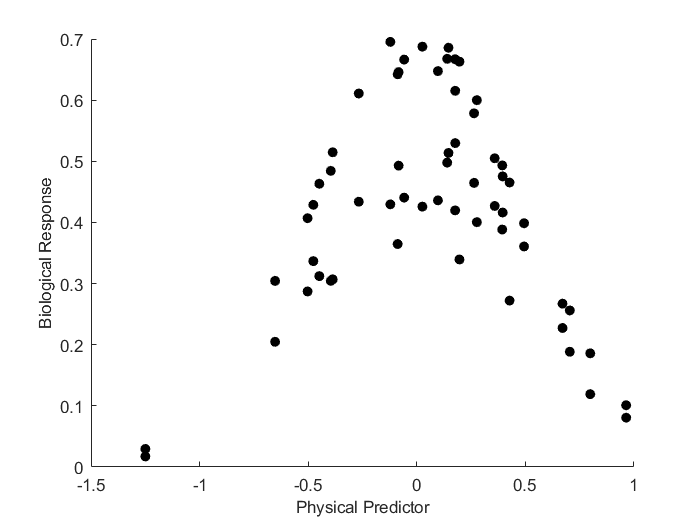


% scatter(xr,z5,[],listcol(1,:),'filled')
scatter(xr,z4,[],'k','filled') %listcol(1,:)
hold on
scatter(xr,z3,[],'k','filled') %listcol(2,:)
xlabel('Physical Predictor','FontSize',10); ylabel('Biological Response','FontSize',10);
print(gcf,sprintf('%sQR_show20.png',wdgraph),'-dpng',plot_reso);
% plot(linspace(min(xr),max(xr),N),zt5,'color',listcol(1,:))
% plot(linspace(min(xr),max(xr),N),zt4,'color','k') %listcol(1,:)
plot(linspace(min(xr),max(xr),N),zt3,'color',listcol(2,:))
hold off
print(gcf,sprintf('%sQR_show21.png',wdgraph),'-dpng',plot_reso);

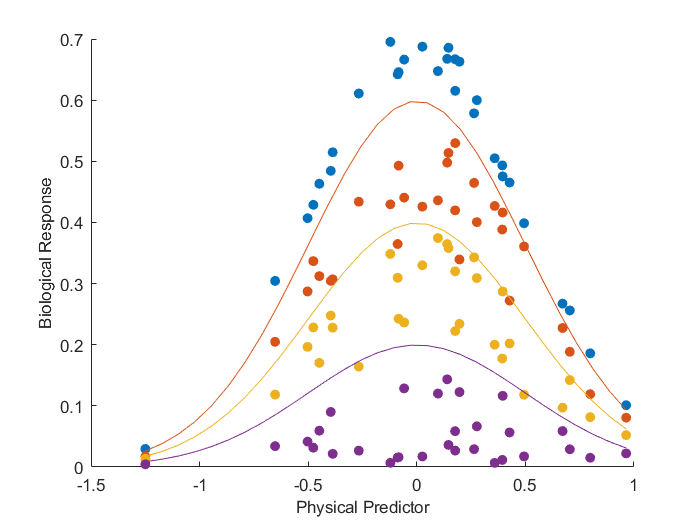


% scatter(xr,z5,[],listcol(1,:),'filled')
scatter(xr,z4,[],'k','filled')
hold on
scatter(xr,z3,[],'k','filled')
scatter(xr,z2,[],'k','filled')
scatter(xr,z1,[],'k','filled')
xlabel('Physical Predictor','FontSize',10); ylabel('Biological Response','FontSize',10);
print(gcf,sprintf('%sQR_show30.png',wdgraph),'-dpng',plot_reso);
scatter(xr,z4,[],listcol(1,:),'filled')
scatter(xr,z3,[],listcol(2,:),'filled')
scatter(xr,z2,[],listcol(3,:),'filled')
scatter(xr,z1,[],listcol(4,:),'filled')
% plot(linspace(min(xr),max(xr),N),zt5,'color',listcol(1,:))
% plot(linspace(min(xr),max(xr),N),zt4,'color',listcol(1,:))
plot(linspace(min(xr),max(xr),N),zt3,'color',listcol(2,:))
plot(linspace(min(xr),max(xr),N),zt2,'color',listcol(3,:))
plot(linspace(min(xr),max(xr),N),zt1,'color',listcol(4,:))
hold off
print(gcf,sprintf('%sQR_show31.png',wdgraph),'-dpng',plot_reso);

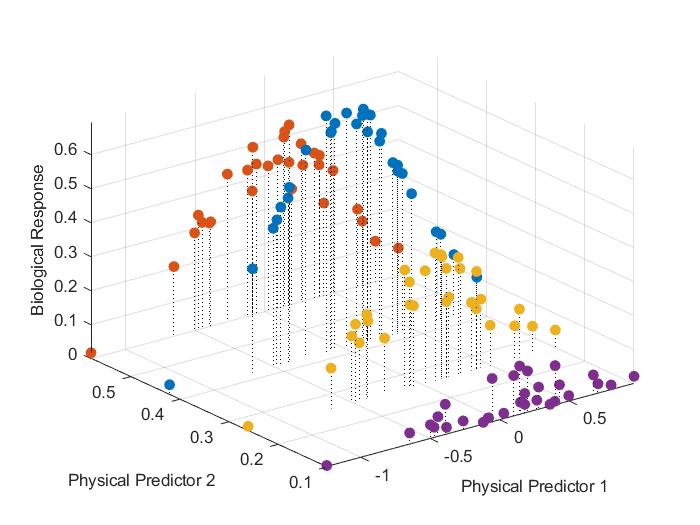


[X,Y]=meshgrid(linspace(min(xr),max(xr),N),linspace(min(yr),max(yr),N/5));

Z1=limfact(1)*exp(-(xr.^2/2)-(yr(1).^2/2))/sqrt(2*pi).*(9+rand(N,1))/10;
    Zt1=limfact(1)*exp(-(X.^2/2)-(Y.^2/2))/sqrt(2*pi);
Z2=limfact(2)*exp(-(xr.^2/2)-(yr(2).^2/2))/sqrt(2*pi).*(9+rand(N,1))/10;
    Zt2=limfact(2)*exp(-(X.^2/2)-(Y.^2/2))/sqrt(2*pi);
Z3=limfact(3)*exp(-(xr.^2/2)-(yr(4).^2/2))/sqrt(2*pi).*(9+rand(N,1))/10;
    Zt3=limfact(3)*exp(-(X.^2/2)-(Y.^2/2))/sqrt(2*pi);
Z4=limfact(4)*exp(-(xr.^2/2)-(yr(3).^2/2))/sqrt(2*pi).*(9+rand(N,1))/10;
    Zt4=limfact(4)*exp(-(X.^2/2)-(Y.^2/2))/sqrt(2*pi);
figure
stem3(xr,repmat(yr(1),N,1),z1,'linestyle',':','Color','k', ...
    'MarkerFaceColor',listcol(4,:),'MarkerEdgeColor',listcol(4,:))
hold on
stem3(xr,repmat(yr(2),N,1),z2,'linestyle',':','Color','k', ...
    'MarkerFaceColor',listcol(3,:),'MarkerEdgeColor',listcol(3,:))
stem3(xr,repmat(yr(4),N,1),z3,'linestyle',':','Color','k', ...
    'MarkerFaceColor',listcol(2,:),'MarkerEdgeColor',listcol(2,:))
stem3(xr,repmat(yr(3),N,1),z4,'linestyle',':','Color','k', ...
    'MarkerFaceColor',listcol(1,:),'MarkerEdgeColor',listcol(1,:))

% surf(X,Y,Zt4,'EdgeColor','flat','LineStyle','none');
% surf(X,Y,Zt3,'EdgeColor','flat'); %,'LineStyle','none'
% surf(X,Y,Zt2,'EdgeColor','flat'); %,'LineStyle','none'
% surf(X,Y,Zt1,'EdgeColor','flat'); %,'LineStyle','none'
hold off
xlabel('Physical Predictor 1','FontSize',10); ylabel('Physical Predictor 2','FontSize',10); zlabel('Biological Response','FontSize',10);
colormap(palette); alpha(.2);
axis tight
% set(gca,'XTickLabel',[], 'YTickLabel', [], 'ZTickLabel', [])
print(gcf,sprintf('%sQR_show40.png',wdgraph),'-dpng',plot_reso);